clear
close all
clc

Consider the linear time-invariant discrete-time system:

    $x(k+1) = A x(k) + B u(k)$,

where $A \in R^{n \times n}$, $B \in \mathbb{R}^{n \times m}$, while $x(k) \in \mathbb{R}^n$ and $u(k) \in \mathbb{R}^m$ denote respectively the state and the input at time $k \in \mathbb{N}$.

Given a user generated open-loop trajectory, both of the state and the control input, starting from the initial condition $x(0)$, the program builds a dynamic state feedback


$$u(k)   = K x(k) + K x(k)$$



$$z(k+1) = F x(k) + G x(k)$$


such that

- is stabilizing

- for the same initial condition $x(0)$ generates the operator's provided trajectory.

#### Liu ship model:

Consider the problem of steering a ship.

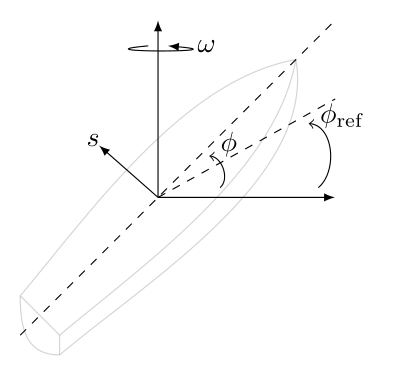

The state variables are the sway velocity $s$, the yaw angular speed $\omega$, and the yaw angle $\phi$. The  control  input $u$ is the rudder angle. The model is presented in [Alessandri et al. 2015](https://www.taylorfrancis.com/chapters/edit/10.1201/b18855-78/system-control-design-autopilot-speed-pilot-patrol-vessel-using-lmis-alessandri-donnarumma-vignolo-figari-martelli-chiti-sebastiani).

We assume that  such a model is not available. But we use it only for simulation puposes

% Liu ship model
n = 3; % the state size 
m = 1; % control input size 

% Continuous-time model of Liu sheep 
A = [-0.8 0.3 0;...
    0.3 -0.8 0;...
    0 1 0];
B = [1 0.5 0]';

sys = ss(A, B, eye(n), zeros(3,1));

% Discrete-time model of Liu sheep
T_camp_sys = 1; % Sampling time [sec]

sysd = c2d(sys, T_camp_sys);

Ad = sysd.A;
Bd = sysd.B;

#### Trajectory generation:

We assume to know a control input sequence $U$generated by an expert operator, and we record the corresponding state trajectory $X$.

In the following we assume that $X$ corresponds to the desired trajecotry $X_d$

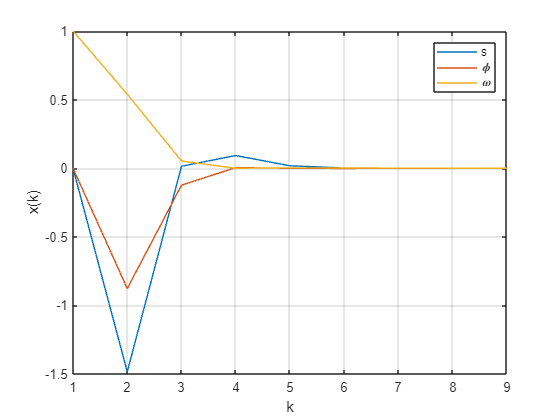

x_0 = [0 0 1]'; % Initial state x(0)
X = x_0; % State trajectory record vector

Ts = 8; % Total simulation time [sec]

x = x_0; % Initialization of the state


U = -[2, -1.1201, -0.1384, 0.0354, 0.0091, -0.0002, -0.0002, 0]; % expert control sequence


% State trajectory record
for t=1:Ts
    x = Ad*x+Bd*U(t);
    X = [X,x];
end
figure()
set(gca, 'defaultAxesTickLabelInterpreter','latex')

plot(X')

xlabel('k')
ylabel('x(k)')
legend('s','\phi','\omega')

X_d = X;
grid

#### Compute the dynamic compensator based on the expert-operator's trajectory:

The following procedure is based on the the syntesys approach described in Section II-A of our paper.

**First step)** We solve the equation:


$$A  X + B U = X P$$


where 


$$P = \left[\begin{array}{ccccc}0 & 0  & \ldots & 0 & p_1 \\ 1 & 0  & \ldots & 0 & p_2 \\ 0 & 1  & \ldots & 0 & \vdots \\ \vdots & \vdots  & \ldots & \vdots & \vdots \\ 0 & 0  & \ldots & 1 & p_N  \end{array}\right]$$


in order to compute the last column of $P$.

X_p = X(:,2:Ts+1);
X = X(:,1:Ts);
p = linsolve(X,X_p(:,Ts)); % last column of the matrix P
P = [zeros(1,Ts-1);eye(Ts-1)]; %first N-1 columns of  the P matrix
P = [P p]; % the final P matrix

**Second step)** We want to synthetize the dynamic compensator


$$z(k+1) = R x(k) + Q z(k)$$



$$u(k)  = T x(k) + S z(k)$$


where $Q\in\mathbb{R}^{(N-n)\times(N-n)}$, $R\in\mathbb{R}^{(N-n)\times n}$, $S\in\mathbb{R}^{m\times(N-n)}$, and $T\in\mathbb{R}^{m\times n}$.

Then, we first create a $(N-n) \times N$ matrix 


$$Z=\left[0~z(1)~z(2)~\cdots~z(N-1)\right]$$


 such that 


$$M = \left[\begin{array}{c} X \\ Z \end{array} \right] = \left[\begin{array}{ccccc}x(0) &x(1)  &x(2) &\cdots  &x(N-1)\\ 0    &z(1)  &z(2) &\cdots  &z(N-1)\end{array}\right]$$


is invertible

Z = [zeros(Ts-n,1) ones(Ts-n,Ts-1)-2*rand(Ts-n,Ts-1)]

Z =          0    0.6620   -0.0940    0.6330   -0.8588    0.3873   -0.2886   -0.8780
         0   -0.2982    0.4074    0.2630   -0.5514   -0.0170    0.2428   -0.7519
         0   -0.4634   -0.4894   -0.2512    0.0264   -0.0215   -0.6232   -0.1003
         0   -0.2955    0.6221   -0.5605    0.1283   -0.6353   -0.0657   -0.2450
         0    0.0982   -0.3736    0.8377    0.1064   -0.5897    0.2985   -0.1741


M = [X;Z];

assert(det(M)~=0,'M is not invertible')

To compute $Q$, $R$, $S$, $T$ we now solve:


$$\left[\begin{array}{cc} T & S \\ R & Q\end{array}\right] \left[ \begin{array}{c} X \\ Z \end{array}\right] = \left[\begin{array}{c} U \\ ZP \end{array}\right]$$


V = Z*P;
TSRQ = [U;V]*inv(M);
T = TSRQ(1:m,1:n);
S = TSRQ(1:m,n+1:Ts);
R = TSRQ(m+1:m+Ts-n,1:n);
Q = TSRQ(m+1:m+Ts-n,n+1:Ts);

#### Closed-loop simulation:

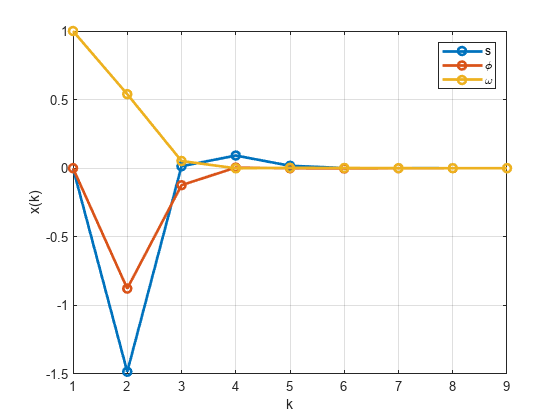

x = x_0; % state initialization
z = zeros(Ts-n,1); % z initialization

X1 = x_0; %trajectory storage
for t=1:Ts
    u=T*x+S*z;
    x_p=Ad*x+Bd*u;
    z_p=Q*z+R*x;
    X1=[X1 x_p];
    x=x_p;
    z=z_p;
end
figure
plot(X1','-o','linewidth',2)
grid
xlabel('k')
ylabel('x(k)')
legend('s','\phi','\omega')

Check that the trajectory of the expert operator mathces with the one obtained by our dynamic compensator when the same initial condition is applied.

assert(all(all(abs(X_d-X1)<1e-10*ones(size(X_d)))),'Fail: the trajectory of the expert operator differs from the one obtained using the dynamic compensator')

#### Closed-loop simulation with different initial condition:

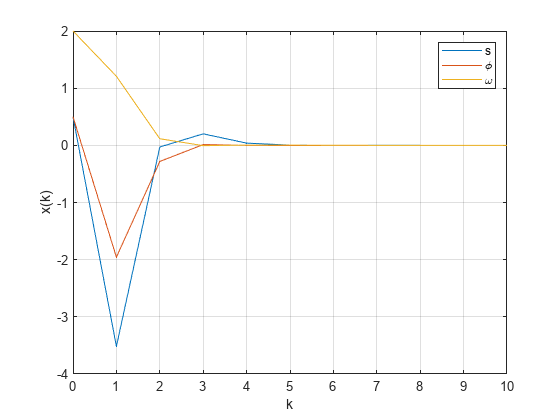

delta_x_0 = [0.5 .5 1]';  % perturbations
x = x_0+delta_x_0; % perturbed initial state

z=zeros(Ts-n,1); % z initialization

X1=x; %trajectory storage
U1=0;

T_sim=10;
for t=1:T_sim
    u=T*x+S*z;
    x_p=Ad*x+Bd*u;
    z_p=Q*z+R*x;
    X1=[X1 x_p]; 
    U1=[U1 u];
    x=x_p;
    z=z_p;
end
figure
plot(0:T_sim,X1')
grid
xlabel('k')
ylabel('x(k)')
legend('s','\phi','\omega')

#### "Continuous-time"-equivalent simulation with different initial condition:

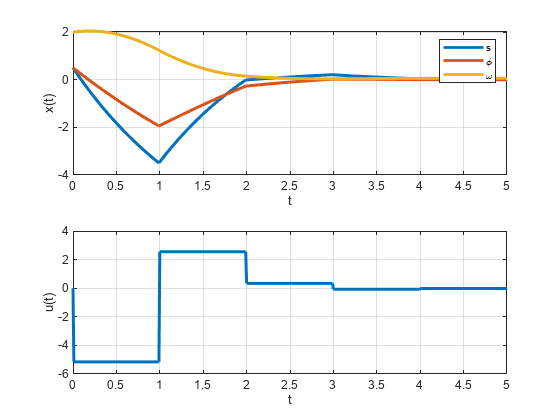

x=x_0+delta_x_0; % perturbed initial state
z=zeros(Ts-n,1); % z initialization
X_plot=x;
U_plot=0;
t_plot=0;

T_sim=5;

% We create a very small sample time \tau (lower then the one used to create the discrete-time system)
div_fact=100; % scaling factor 
tau=T_camp_sys/div_fact; % sample time of forward-Euler discretiation of the contiuous time system (sys) << T_camp_sys

for t=tau:tau:T_sim
    h=floor(t/T_camp_sys)+2;
    u=U1(h);
    x=x+tau*(A*x+B*u);
    X_plot=[X_plot x];
    t_plot=[t_plot t];
    U_plot=[U_plot u];
end

figure
subplot(2,1,1), plot(t_plot,X_plot', 'linewidth',2)
xlabel('t')
ylabel('x(t)')
legend('s','\phi','\omega')
grid
subplot(2,1,2), plot(t_plot,U_plot','linewidth',2) 
grid
xlabel('t')
ylabel('u(t)')

We now evaluate the maximum egienvalues of the matrices $P$ and $Q$

aut_P = eig(P)

aut_P =   -0.3483 + 0.0000i
  -0.2099 + 0.2552i
  -0.2099 - 0.2552i
   0.3326 + 0.0000i
   0.2022 + 0.2352i
   0.2022 - 0.2352i
   0.0156 + 0.2841i
   0.0156 - 0.2841i


max_aut_P = max(abs(eig(P)))

max_aut_P = 0.3483

aut_F = eig(Q)

aut_F =    0.1441 + 0.2292i
   0.1441 - 0.2292i
  -0.1714 + 0.2510i
  -0.1714 - 0.2510i
  -0.3249 + 0.0000i


max_aut_F = max(abs(eig(Q)))

max_aut_F = 0.3249